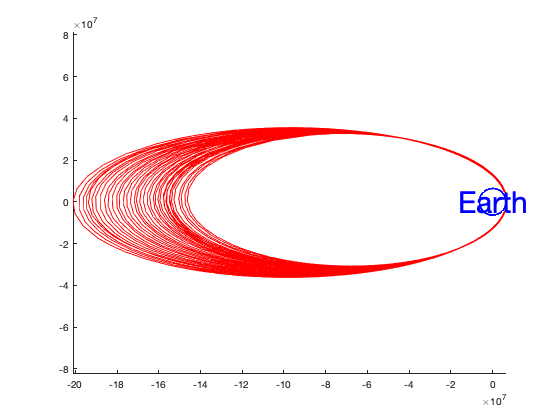

radius_earth = 6371071; % m
radius_orbit = 257495 + radius_earth; % m
[timestamps, positions, velocities] = simulate_launch([0 10000000], [radius_earth + 1, 0, 0, -11000]);

clf; axis equal; hold on;
plot(positions(:, 1), positions(:, 2), "r");
viscircles([0 0], radius_earth, 'Color', 'blue');
text(0, 0, "Earth", "HorizontalAlignment","center", "VerticalAlignment","middle", "Color", "blue", "FontSize", 30);
hold off;